% =========================================================================
%       CONFIGURACIÓN DEL MODELO DE PRESION 
% =========================================================================
% Este bloque define los parámetros del modelo hidráulico y genera la
% función de transferencia en lazo abierto y cerrado, tanto en tiempo
% continuo como discreto.
% =========================================================================

clear; clc; close all;

% --- Parámetros específicos del modelo hidráulico (de la tabla) ---
C1 = 0.238e-6;      % Capacitancia hidráulica 1 (m^3/Pa)
C2 = 0.98e-6;       % Capacitancia hidráulica 2 (m^3/Pa)
R1 = 306.0093e3;    % Resistencia hidráulica 1 (Pa*s/m^3)
R2 = 306.0093e3;    % Resistencia hidráulica 2 (Pa*s/m^3)


% Definición de la variable de Laplace 's'
s = tf('s');

% --- Construcción de la función de transferencia del sistema hidráulico ---
% G(s) = P2(s)/P1(s) = (R2 * C2) / ((R1*R2*C2^2)*S + (C2*R1 + C2*R2))
num = R2 * C2;
den = (R1 * R2 * C2^2) * s + (C2 * R1 + C2 * R2);

% Función de transferencia de la planta (Sistema Hidráulico)
disp('Función de transferencia del sistema en lazo abierto (Continua):')

Función de transferencia del sistema en lazo abierto (Continua):


G = num / den

G =
 
        0.2999
  ------------------
  0.08993 s + 0.5998
 
Continuous-time transfer function.
Model Properties



% Función de transferencia en lazo cerrado (retroalimentación unitaria)
disp('Función de transferencia del sistema en lazo cerrado (Continua):')

Función de transferencia del sistema en lazo cerrado (Continua):


G1 = feedback(G, 1)

G1 =
 
        0.2999
  ------------------
  0.08993 s + 0.8997
 
Continuous-time transfer function.
Model Properties


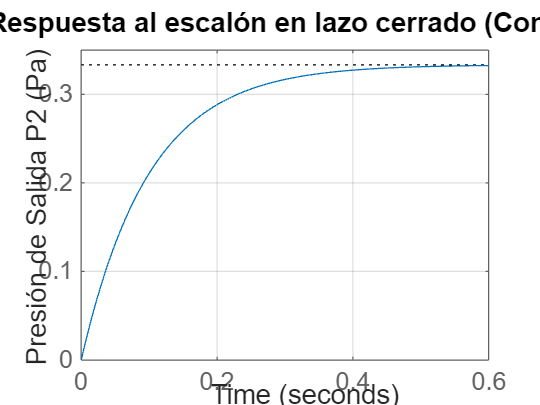


% --- Gráficas del sistema continuo ---
figure;
step(G1); % Se grafica comúnmente la respuesta en lazo cerrado
grid on;
title("Respuesta al escalón en lazo cerrado (Continuo)");
ylabel('Presión de Salida P2 (Pa)');



% =========================================================================
%                         ANÁLISIS DISCRETO
% =========================================================================

% Discretización de la planta
Ts = 0.001; % Tiempo de muestreo
disp('Función de transferencia en lazo abierto (Discreta):')

Función de transferencia en lazo abierto (Discreta):


G_z = c2d(G, Ts, 'tustin'); % 'tustin' es un método común de discretización

% Función de transferencia discreta en lazo cerrado
disp('Función de transferencia en lazo cerrado (Discreta):')

Función de transferencia en lazo cerrado (Discreta):


G1_z = feedback(G_z, 1)

G1_z =
 
  0.001662 z + 0.001662
  ---------------------
    1.002 z - 0.9917
 
Sample time: 0.001 seconds
Discrete-time transfer function.
Model Properties


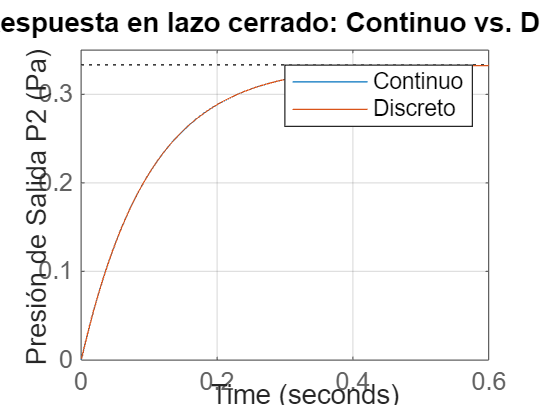


% --- Gráficas de comparación Continuo vs. Discreto ---
figure;
step(G1);
hold on;
step(G1_z);
hold off;
grid on;
title('Respuesta en lazo cerrado: Continuo vs. Discreto');
ylabel('Presión de Salida P2 (Pa)');
legend('Continuo', 'Discreto');


% Extracción de datos de la función de transferencia discreta
disp('Parámetros del sistema discreto en lazo abierto:');

Parámetros del sistema discreto en lazo abierto:


NumZ = G_z.Numerator{1}   % Coeficientes del numerador discreto

NumZ =     0.0017    0.0017


DenZ = G_z.Denominator{1}   % Coeficientes del denominador discreto

DenZ =     1.0000   -0.9934


[z, p, k] = zpkdata(G_z, 'v') % Ceros, polos y ganancia discretos

z = -1

p = 0.9934

k = 0.0017



% =========================================================================
%                  CONFIGURACIÓN DEL CONTROLADOR PI
% =========================================================================
% Este bloque define un controlador PI discreto y analiza el
% comportamiento del sistema en lazo cerrado con dicho controlador.
% =========================================================================

% Coeficientes del controlador PI obtenidos por asignación de polos
Kp = 6.156;     % Ganancia Proporcional
Ki = 161.232;   % Ganancia Integral

% --- Construcción del controlador PI Discreto ---

% Término Proporcional
C_p = tf(Kp, 1, Ts);

% Término Integral: Ki * Ts / (z - 1)
% Se discretiza el término integral Ki/s usando el método de Tustin (implícito en la fórmula)
C_i = tf(Ki * Ts, [1 -1], Ts);

% Controlador PI completo (suma de los términos)
disp('Función de transferencia PI discreta:')

Función de transferencia PI discreta:


C_pi = C_p + C_i

C_pi =
 
  6.156 z - 5.995
  ---------------
       z - 1
 
Sample time: 0.001 seconds
Discrete-time transfer function.
Model Properties




% Sistema en lazo cerrado con el controlador PI
disp('Función de transferencia del sistema controlado:')

Función de transferencia del sistema controlado:


T = feedback(C_pi * G_z, 1)

T =
 
  0.01023 z^2 + 0.0002679 z - 0.009962
  ------------------------------------
      1.01 z^2 - 1.993 z + 0.9834
 
Sample time: 0.001 seconds
Discrete-time transfer function.
Model Properties


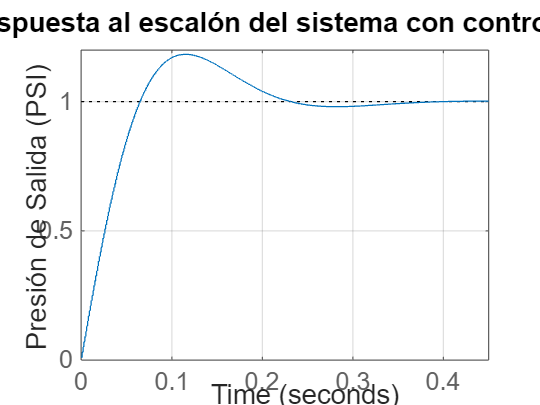


% --- Gráfica del sistema controlado ---
figure;
step(T);
grid on;
title('Respuesta al escalón del sistema con controlador PI');
ylabel('Presión de Salida (PSI)');